# BME 2740 Interactive Lecture 16

# By: Dr . Asad Mirza

# Adapted From: Dr. Ilmar Tamames

#### Parameterizing ODE Systems

**Parameterizing an ODE system means writing your differential equations in a way that allows you to change system parameters without having to rewrite the equations or the simulation code.**

Suppose we would like to simulate a system across a potentially vast range of different parameter choices, for example, simulating the effect of changes in masses, spring stiffness, or even gravity in the spring-mass system:

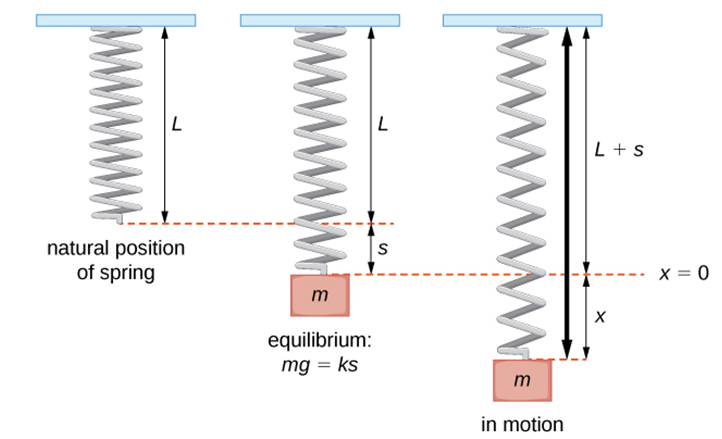


$$m\frac{d^2 x}{dt^2 }=mg-k\left(m*\frac{g}{k}+x\right)$$


How can we achieve such a thing programmatically.

#### Example 1

Plot the system over 50 seconds and with $\frac{\textrm{dx}\left(0\right)}{\textrm{dt}}=0$ and $x\left(0\right)=0\ldotp 1$. Compare for mass equal to 0.1, 0.5, 1 and 5. 

First transform the differential equation into a system of 1st order differential equations using its state system form. 


$$\begin{array}{l}
x=s_1 \\
\frac{\textrm{dx}}{\textrm{dt}}=s_2 
\end{array}$$



$$\frac{ds_1 }{\textrm{dt}}=s_2$$



$$\frac{{\textrm{ds}}_2 }{\textrm{dt}}=g-\frac{k\left(m*\frac{g}{k}+s_1 \right)}{m}$$


% State-Space Representation of a Mass-Spring System
% STEP 1 : Define system parameters
g = -9.81;      % Acceleration due to gravity (m/s^2)
k = 0.05;      % Spring constant (N/m)
y1ini = 0.1;   % Initial position of mass (m)
dy1ini = 0;    % Initial velocity of mass (m/s)
tspan = [0 50]; % Simulation time span (s)
mvals = [0.1, 0.5, 1, 5]; % Array of mass values (kg)

We want to solve it numerically using MATLAB's `ode45`.

However, `ode45` requires a system of first-order differential equations.


% STEP 2: Define the system of ODEs as an anonymous function
% s(1) = position, s(2) = velocity
% ds(1)/dt = s(2)
% ds(2)/dt = g - (k/m) * (m*g/k + s(1))
f = @(t, s, m) [s(2); 
                g - k * (m * g / k + s(1)) / m];

So how do we parametize (aka change a unit automtically in) the system? We use a `for` loop:

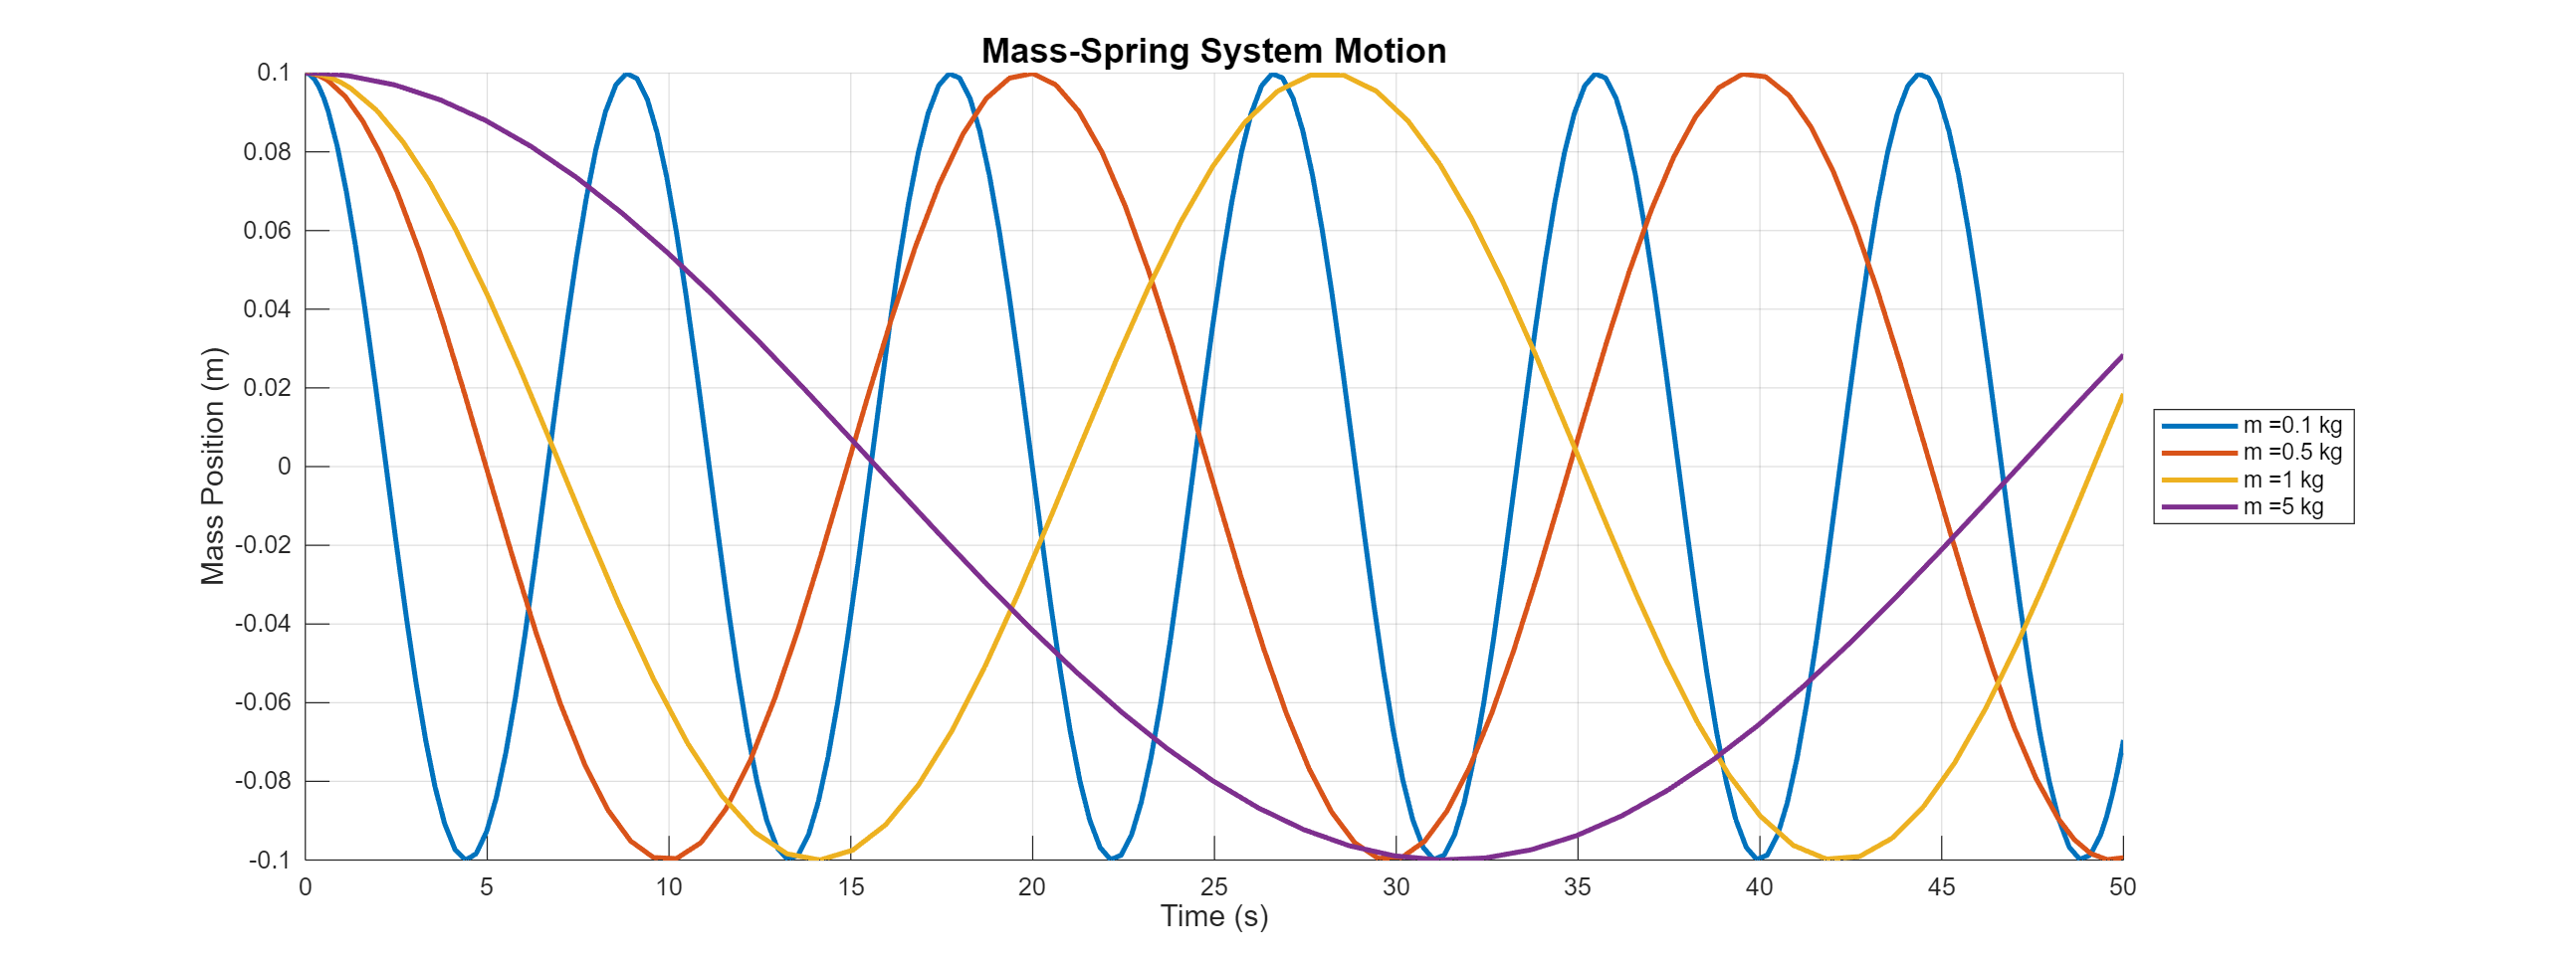


% STEP 3: Solve and plot for each mass value
for i = 1:length(mvals)
    m = mvals(i); % Set current mass
    fnew = @(t, s) f(t, s, m); % Parameterized function for ode45
                    % ^ This is just our old fucntion f = @(t, s, m) [s(2); 
                                                                    % g - k * (m * g / k + s(1)) / m];
    [t, s] = ode45(fnew, tspan, [y1ini, dy1ini]); % Solve ODE
    
    % Plot results
    plot(t, s(:,1), 'LineWidth', 2);
end

% STEP 4: Formatting the plot
figure('Units','normalized','Position',[0 0 5 3]);
hold on;
grid on;
xlabel('Time (s)', 'FontSize', 12);
ylabel('Mass Position (m)', 'FontSize', 12);
legend(strcat('m = ', string(mvals), ' kg'), 'Location', 'eastoutside');
title('Mass-Spring System Motion', 'FontSize', 14);
hold off;

#### Example 2

Numerically integrate the van der Pol equation (below) using ode45 to determine the value of x at 10 given that $\frac{\textrm{dx}\left(0\right)}{\textrm{dt}}=0$ and $x\left(0\right)=2$. 

Compute the integral for 10 different values of μ, linearly spaced on the interval [0.01 10], and plot the results, x(t) as a function of t, on the same graph. Report the final result for x at t=10 for each case.


$$\frac{d^2 x}{dt^2 }-\mu {\left(1-x^2 \right)}\frac{dx}{\textrm{dt}}+x=0$$


First transform the differential equation into a system of 1st order differential equations using its canonical form. 


$$x=s_1$$



$$x^{\prime } =s_2$$



$$\frac{ds_1 }{dt}=s_2$$



$$\frac{ds_2 }{dt}=\mu {\left(1-{s_1 }^2 \right)}s_2 -s_1$$


% Van der Pol Oscillator Simulation
% The system is defined in canonical form:
%   s1 = x
%   s2 = x'
%   ds1/dt = s2
%   ds2/dt = mu * (1 - s1^2) * s2 - s1
%
% where `mu` controls the nonlinearity and damping of the system.

% Define simulation parameters
tspan = [0.01, 10];      % Time span for simulation (s)
mu_vals = linspace(0.01, 10, 10); % Range of mu values
s0 = [2; 0];             % Initial conditions [position; velocity]

% Define the Van der Pol oscillator equations
% y(1) = position (x), y(2) = velocity (dx/dt)
f = @(t, s, mu) [s(2); 
                 mu * (1 - s(1)^2) * s(2) - s(1)];

% Set up the figure for plotting
figure('Units','normalized','Position',[0 0 5 3]); 
hold on; 
grid on;

% Solve and plot for each value of mu
for k = 1:length(mu_vals)
    mu = mu_vals(k); % Current mu value
    [t, s] = ode45(@(t, s) f(t, s, mu), tspan, s0); % Solve ODE



Final y1 for mu = 0.01: -1.6893
Final y1 for mu = 1.12: -1.9922
Final y1 for mu = 2.23: 1.2335
Final y1 for mu = 3.34: 1.879
Final y1 for mu = 4.45: -0.40784
Final y1 for mu = 5.56: -1.4102
Final y1 for mu = 6.67: -1.6616
Final y1 for mu = 7.78: -1.8061
Final y1 for mu = 8.89: -1.9039
Final y1 for mu = 10: -1.973


NOTICE THE DIFFRENCE IN FROMAT!!

## Example 1: Using `fnew`

`m = mvals(i); % `Select the current mass.

`fnew = @(t, s) f(t, s, m)``; % `Create a new function called `fnew` that fixes the mass.

`[t, s] = ode45(fnew, tspan, [y1ini, dy1ini]); % `Pass `fnew` to `ode45`.

## Example 2: Without `fnew`

matlab

`mu = mu_vals(k); % `Select the current value of μ

`[t, s] = ode45(``@(t, s) f(t, s, mu)``, tspan, s0); % `Create the anonymous function directly inside `ode45 AND p`ass that function to `ode45`

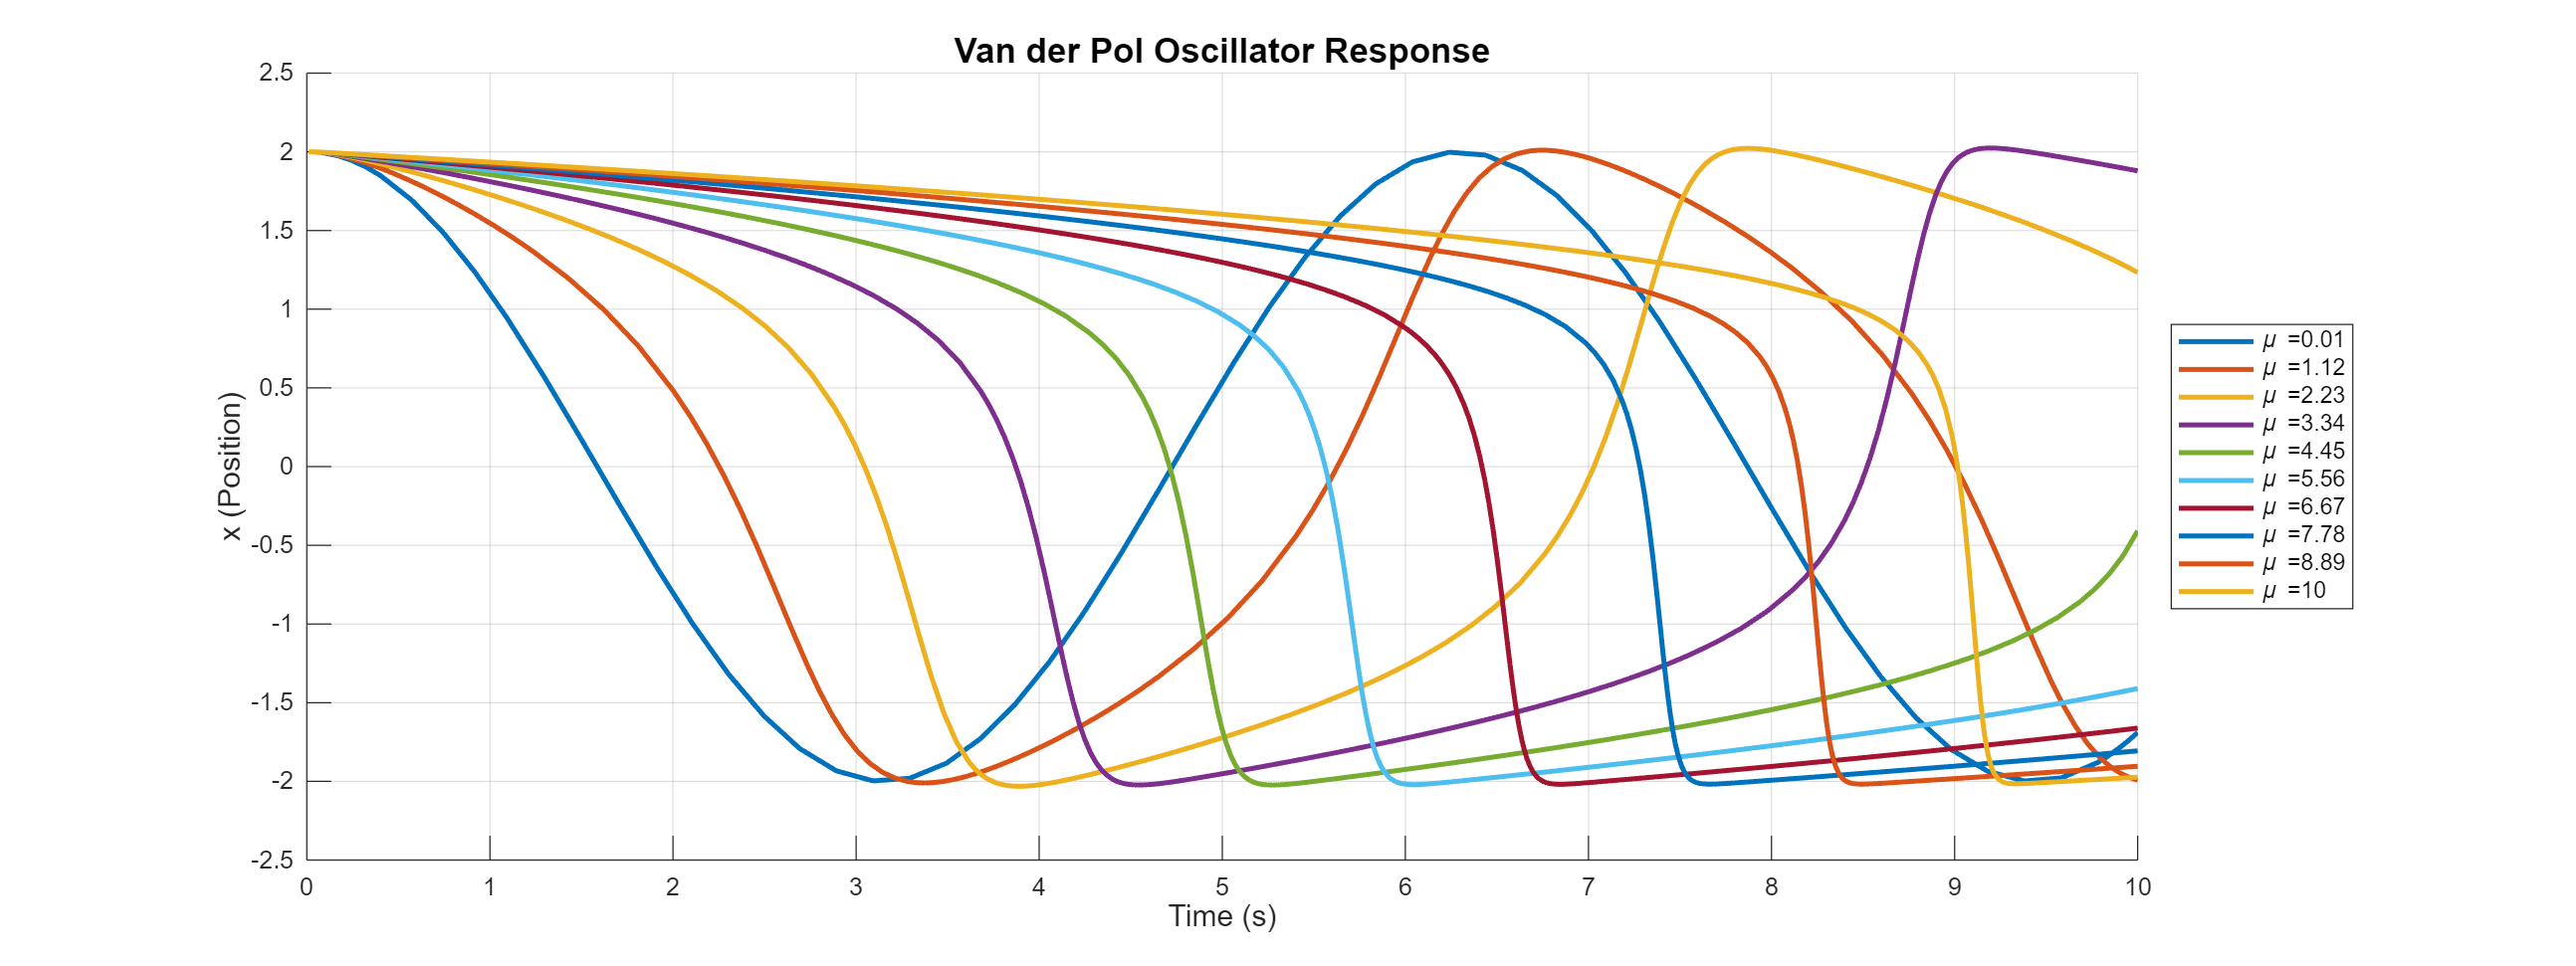

    
    % Plot results
    plot(t, s(:,1), 'LineWidth', 2);
    
    % Display the final position value in the command window
    disp(['Final y1 for mu = ', num2str(mu), ': ', num2str(s(end,1))]);
end


% Formatting the plot
xlabel('Time (s)', 'FontSize', 12);
ylabel('x (Position)', 'FontSize', 12);
legend(strcat('\mu = ', string(mu_vals)), 'Location', 'eastoutside');
title('Van der Pol Oscillator Response', 'FontSize', 14);
hold off;

#### Stability and Stiffness: Example 3

As a junior member of the engineering design team for GlucoFlow Technologies Inc., you are asked to provide an analysis of their newest insulin sensor in their glucose control system for diabetes. The sensor is a polymer gel that intakes glucose ($C_G$) and releases insulin ($C_I$) depending on the relative concentration of these species in the blood, which varies as a function of distance from the blood vessel, z. The science advisory team has provided you with the following governing equations:


$$\frac{dC_G }{dz}=14C_G -2C_G^2 -C_G C_I$$



$$\frac{dC_I }{dz}=16C_I -2C_I^2 -C_G C_I$$


If we integrate this system from 0 to 1, with $C_G \left(0\right)=2$ and  $C_I \left(0\right)=1$ will we obtain accurate results? Does this system have a stable steady state? Is it stiff?

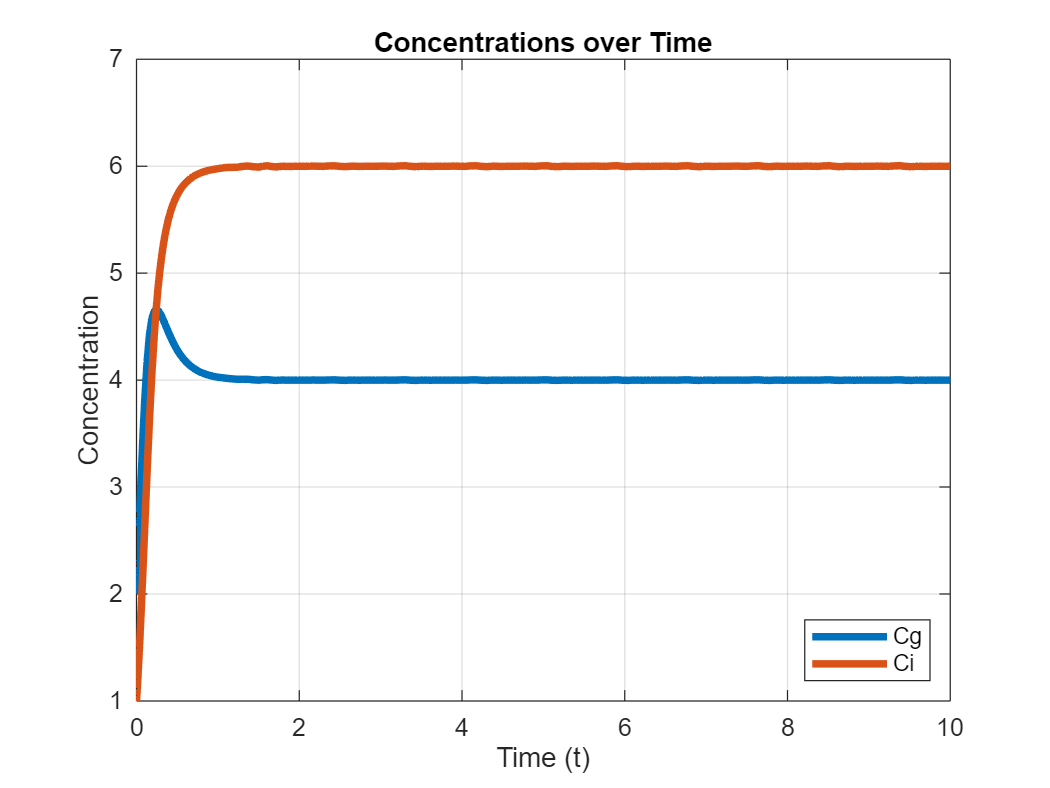

clear;  % Clear workspace

% Set up variables for time span and initial conditions
tspan = [0 10];       % Time range from 0 to 10
s0 = [2, 1];          % Initial conditions [Cg, Ci] where Cg = 2 and Ci = 1

% Define the system of ODEs
% The system represents the dynamics of two concentrations (Cg and Ci) over time
f = @(t, y)  [ 14*y(1) - 2*y(1)^2 - y(1)*y(2);  % Rate of change of Cg
               16*y(2) - 2*y(2)^2 - y(1)*y(2) ];  % Rate of change of Ci

% Solve the system using ode45 solver
[t, s] = ode45(f, tspan, s0);

% Plot the solution
figure;  % Create a new figure window
plot(t, s,'LineWidth',3);  % Plot both Cg and Ci over time
xlabel('Time (t)');  % Label for x-axis
ylabel('Concentration');  % Label for y-axis

legend('Cg', 'Ci', 'Location', 'southeast');  % Add legend to identify Cg and Ci
title('Concentrations over Time');  % Title for the plot
grid on;  % Add grid for better visualization

#### Stiffness

Stiffness happens when a differential equation has a solution that changes slowly, but also has other nearby solutions that change very quickly. This forces numerical solvers to take very small steps to get accurate results.

Stiffness mainly affects computational speed.

Stiffness is a subtle, difficult concept in the numerical solution of ordinary differential equations.

An ordinary differential equation problem is stiff if the solution being sought is varying slowly, but there are nearby solutions that vary rapidly, so the numerical method must take small steps to obtain satisfactory results.

Stiffness is an efficiency issue. If we weren't concerned with how much time a computation takes, we wouldn't be concerned about stiffness. Nonstiff methods can solve stiff problems; they just take a long time to do it.

This following code compares three MATLAB ODE solvers:

clear;  % Clear workspace
% Set up the time span and initial conditions for solving the system
tspan = [0 10000];  % Time range from 0 to 10000
s0 = [2, 1];        % Initial conditions for the populations [Cg, Ci]

% Define the system of ODEs
f = @(t, y)  [ 14*y(1) - 2*y(1)^2 - y(1)*y(2);  % Rate of change of Cg
               16*y(2) - 2*y(2)^2 - y(1)*y(2) ];  % Rate of change of Ci




% Compare the performance of different ODE solvers for tspan = [0, 10000]

`ode45`**:** A standard solver for nonstiff problems.

% Use ode45 solver
tic  % Start timer
[t, s] = ode45(f, tspan, s0);                                    % Solve using ode45
toc  % Stop timer and display time taken

Elapsed time is 0.197090 seconds.


`ode23`**:** Another solver for nonstiff problems.

% Use ode23 solver
tic  % Start timer
[t, s] = ode23(f, tspan, s0);                                    % Solve using ode23
toc  % Stop timer and display time taken

Elapsed time is 0.111910 seconds.


`ode15s`: A solver designed for **stiff ****problems.**

% Use ode15s solver
tic  % Start timer
[t, s] = ode15s(f, tspan, s0);                                  % Solve using ode15s
toc  % Stop timer and display time taken

Elapsed time is 0.015873 seconds.


Now compare the performance:

% Compare the performance of different ODE solvers for tspan = [0, 1000000]
tspan = [0 1000000];  % Extended time range
% Use ode45 solver for larger time span
tic  % Start timer
[t, s] = ode45(f, tspan, s0);  % Solve using ode45
toc  % Stop timer and display time taken

Elapsed time is 17.952883 seconds.


% Use ode23 solver for larger time span
tic  % Start timer
[t, s] = ode23(f, tspan, s0);  % Solve using ode23
toc  % Stop timer and display time taken

Elapsed time is 10.716651 seconds.


% Use ode15s solver for larger time span
tic  % Start timer
[t, s] = ode15s(f, tspan, s0);  % Solve using ode15s
toc  % Stop timer and display time taken

Elapsed time is 0.012547 seconds.


#### Quiver

`TIP: `[`quiver`](https://www.mathworks.com/help/matlab/ref/quiver.html)`(`[`X`](https://www.mathworks.com/help/matlab/ref/quiver.html#mw_3e9db111-ea01-407e-9f2c-a84bbd1aa81b)`,`[`Y`](https://www.mathworks.com/help/matlab/ref/quiver.html#mw_71a25f0f-3648-4637-a57a-75112ef21c93)`,`[`U`](https://www.mathworks.com/help/matlab/ref/quiver.html#mw_71819171-94c7-4eb6-9072-0b761b2b0847)`,`[`V`](https://www.mathworks.com/help/matlab/ref/quiver.html#mw_62ea2524-df58-47fc-9219-cc50bd06b105)`)` plots arrows with directional components `U` and `V` at the Cartesian coordinates specified by `X` and `Y`. For example, the first arrow originates from the points `X(1)` and `Y(1)`, extends horizontally according to `U(1)`, and extends vertically according to `V(1)`. By default, the `quiver` function scales the arrow lengths so that they do not overlap.

**A quiver plot is used in MATLAB to visualize a vector field using arrows. Each arrow shows the direction and strength of a vector at a specific point.**

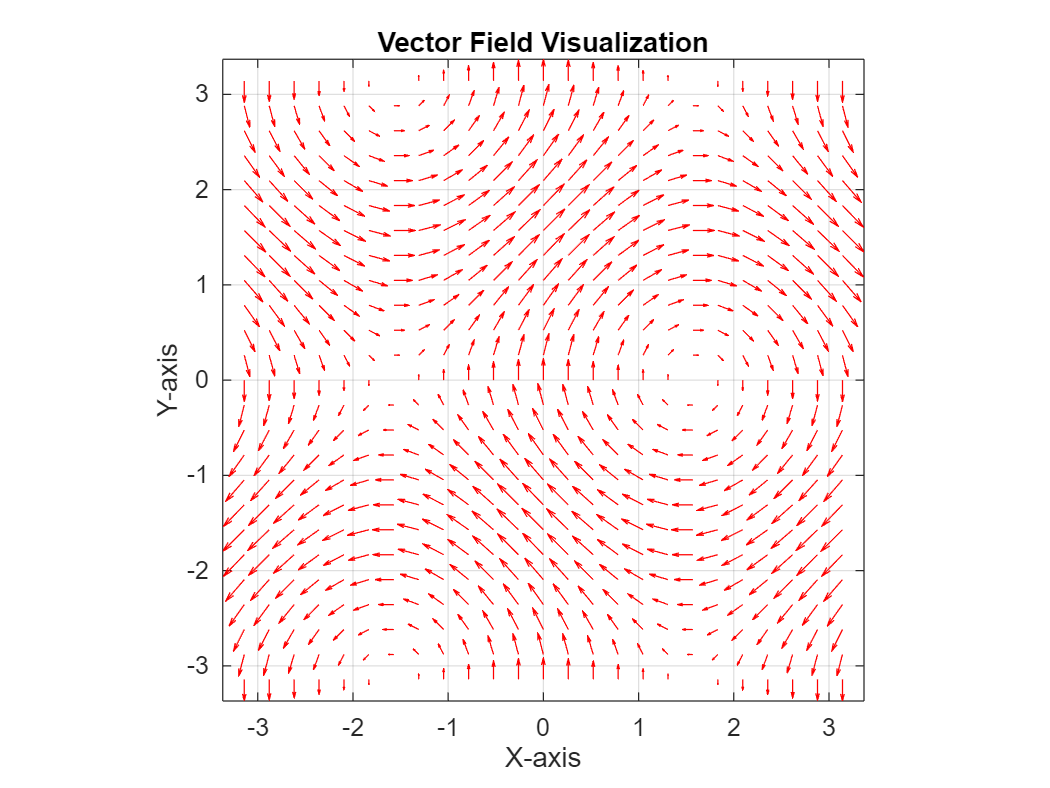

% Vector Field Plot using Quiver in MATLAB

% Define the grid points for the vector field
[X, Y] = meshgrid(linspace(-pi,pi,25),linspace(-pi,pi,25)); % Creates a 25x25 grid in the XY plane
% ^X and Y define where the arrows start.

% Define the vector components
U = sin(Y); % horizontal direction 
V = cos(X); % vertical direction 

% Plot the vector field using quiver
figure; % Open a new figure window
quiver(X, Y, U, V, 'r'); % plots the vector field using red arrows
% ^ creates the arrows on the graph.

% Formatting the rest of the plot for better visualization
axis tight; % Ensures equal scaling for X and Y axes
xlabel('X-axis'); % Label for X-axis
ylabel('Y-axis'); % Label for Y-axis
title('Vector Field Visualization'); % Title of the plot
grid on; % Enable grid for better readability
axis equal % eeps the same scale on both axis

#### The Phase Portrait

Phase portraits are highly useful tools for analyzing “autonomous systems”, meaning systems that only depend on the dependent variable (x,y,etc), not the independent (t). These diagrams demonstrate the stable equilibria of the system.

Essentially, its a graph that shows how the prey and predator populations interact with each other over time.

The important difference between the previous graph and this one is:

- Time-series graph: Shows how prey and predator populations change as time passes.

- Phase portrait: Shows how the prey and predator populations change relative to each other, without explicitly showing time.

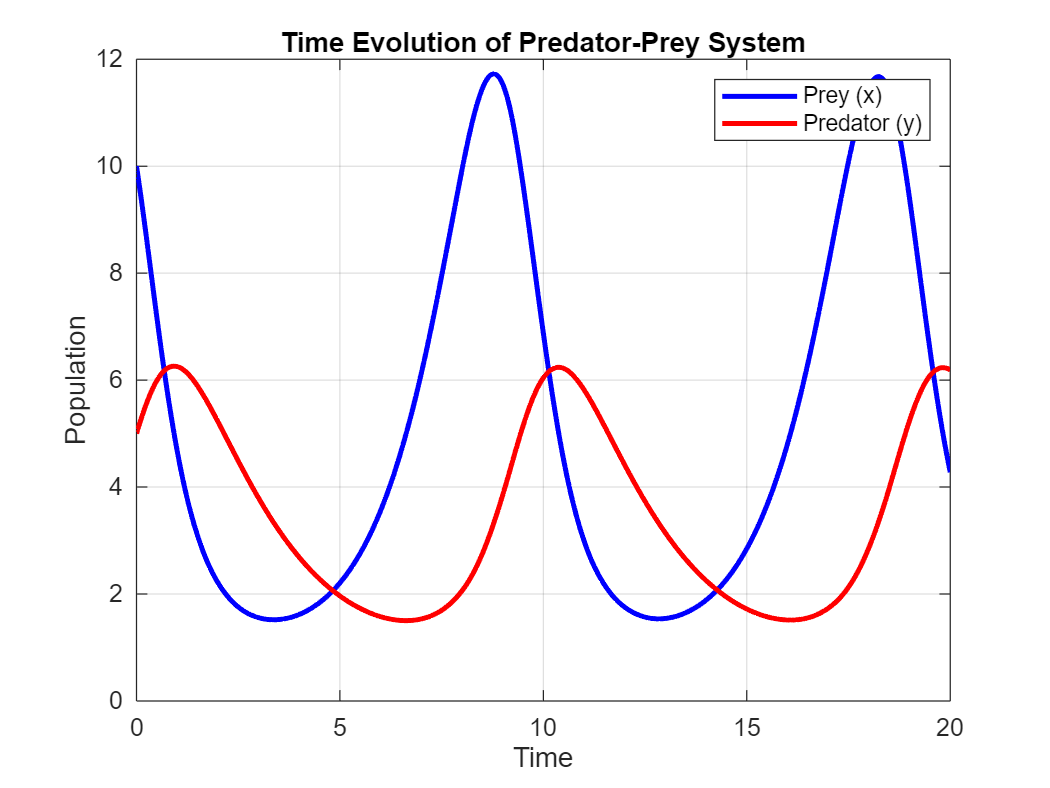

% Define parameters
alpha = 1;   % Prey birth rate
beta = 0.3;  % Prey death rate due to predation
gamma = 0.5;   % Predator death rate
delta = 0.1; % Predator growth rate due to predation

% Define system of equations
f = @(t, y) [alpha*y(1) - beta*y(1)*y(2);  % dx/dt (prey equation)
             delta*y(1)*y(2) - gamma*y(2)]; % dy/dt (predator equation)

% Solve ODEs
tspan = linspace(0,20,1000); % Time interval
s0 = [10; 5];   % Initial conditions (prey = 10, predator = 5)
% s0 = [gamma/delta; alpha/beta];   % Initial conditions (prey = gamma/delta, predator = alpha/beta)
[t, s] = ode45(f, tspan, s0);
    
% Plot time series solution
figure;
plot(t, s(:,1), 'b', 'LineWidth', 2); hold on;
plot(t, s(:,2), 'r', 'LineWidth', 2);
xlabel('Time'); ylabel('Population');
legend('Prey (x)', 'Predator (y)');
title('Time Evolution of Predator-Prey System');
grid on;

This is the new part: **The Phase Portrait**

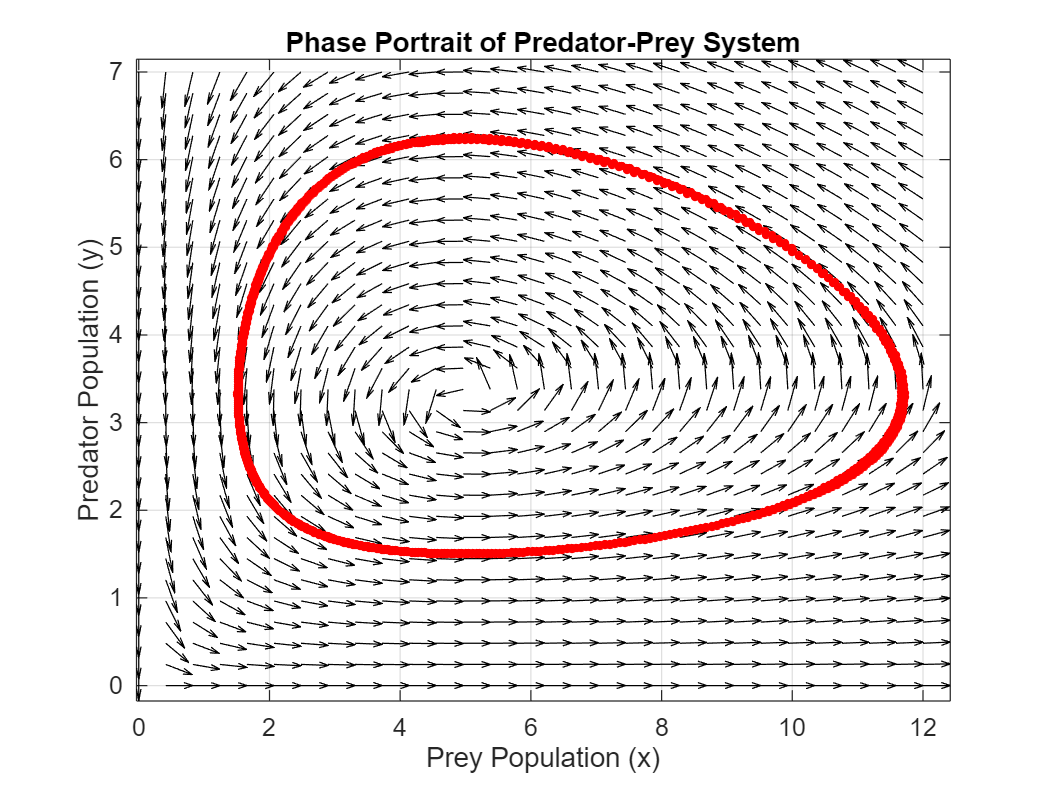


% Define grid for phase portrait
n = 30;
x_vals = linspace(0, max(s0)+2, n); % Prey axis
y_vals = linspace(0, min(s0)+2, n); % Predator axis
[xm, ym] = meshgrid(x_vals, y_vals); % Create mesh grid (combines the horizontal and vertical values into a two-dimensional grid)

% Compute vector field
% calculates these two derivatives at every point on the grid.
dx = alpha*xm - beta*xm.*ym;
dy = delta*xm.*ym - gamma*ym;

% Normalize vectors for better visualization
mag = sqrt(dx.^2 + dy.^2); % calculates the magnitude (length) of each vector
% Normalization makes the arrows approximately equal in length, 
% allowing us to focus on their directions rather than their magnitudes.

% Plot phase portrait
figure
quiver(xm, ym, dx./mag, dy./mag, 'k'); 
hold on;
plot(s(:,1), s(:,2), '.r', 'LineWidth', 2,'MarkerSize',10); % Plot trajectory
xlabel('Prey Population (x)');
ylabel('Predator Population (y)');
title('Phase Portrait of Predator-Prey System');
axis tight
grid on;

**Meaning of the Phase Portrait**

A phase portrait provides insight into the long-term behavior of the system by showing trajectories in the x-y plane, where:

- Each trajectory represents a different initial condition (starting populations of prey and predator).

- The arrows indicate the direction of population change over time.

- The system exhibits cyclic orbits, meaning the populations of both species rise and fall in a periodic manner.

- The equilibrium points (fixed points) occur where both derivatives are zero, meaning no change in population over time. In this case, we typically see:

- A trivial equilibrium at (0,0) (both species extinct), not interesting.

- A non-trivial equilibrium at $\left(x^* ,y^* \right)=\left(\frac{\gamma }{\delta \;},\frac{\alpha }{\beta \;}\right)$ where predator and prey coexist in a delicate steady state.

**Biological Interpretation**

- When prey (x) increases, predators (y) have more food, so their population also rises.

- As the predator population grows, they consume more prey, causing the prey population to decline.

- With fewer prey available, the predator population also starts to decline due to lack of food.

- Once the predator population is low, the prey population can recover, and the cycle repeats.

This cyclic pattern is observed in real ecosystems where predator and prey populations fluctuate over time. The phase portrait captures this oscillatory nature of the predator-prey relationship, showing how populations can persist without leading to extinction (in the absence of external factors like disease or environmental changes).

#### Unstable Spiral (Spiral Source)

- The trajectories spiral outward.

- The origin is an unstable equilibrium.


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=0\ldotp 5x-y\\
\frac{\textrm{dy}}{\textrm{dt}}=x+0\ldotp 5y
\end{array}$$


% Unstable Spiral Example with Phase Plot and Animation
clear; clc; close all;

% Define the system of ODEs
f = @(t, Y) [0.5*Y(1)-Y(2);Y(1)+0.5*Y(2)]; 

% Set up the time span and initial conditions
tspan = [0 10];
s0 = [0.02; 0];  % Initial condition


Now se set up the Phase Plot

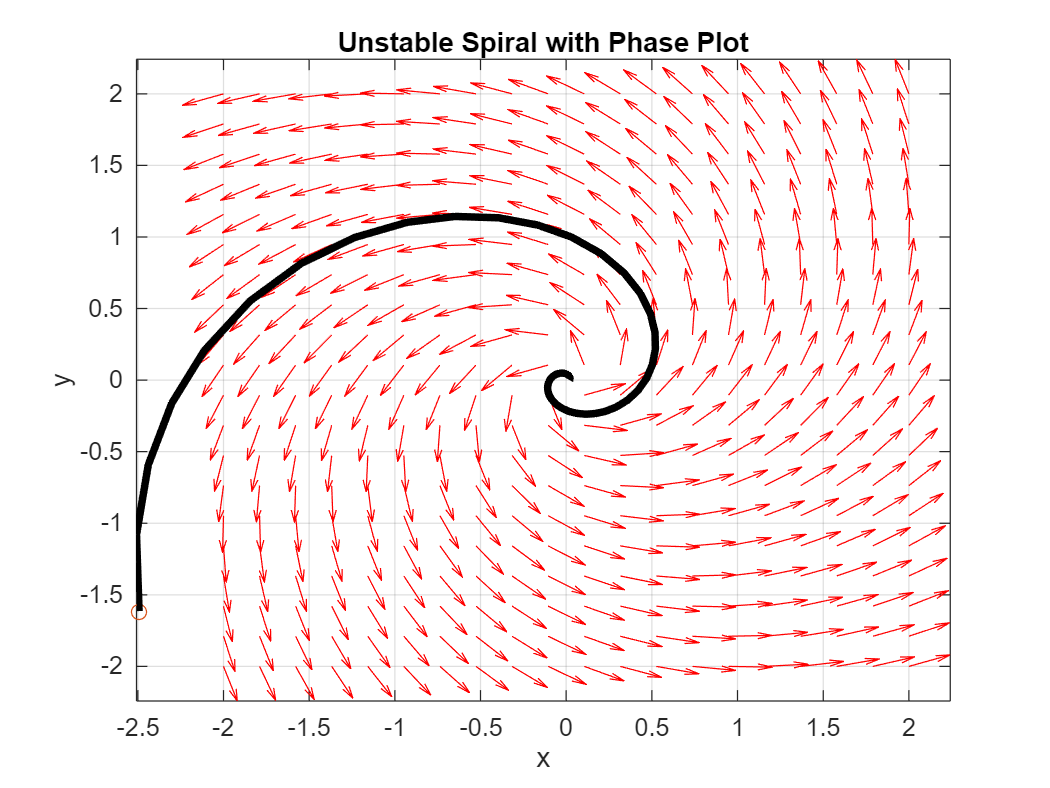


% Create a grid for the phase plot
y1 = linspace(-2, 2, 20);
y2 = linspace(-2, 2, 20);
[x, s] = meshgrid(y1, y2);
u = zeros(size(x));
v = zeros(size(s));

% Compute the vector field for phase plot
% ( Calculates the direction and magnitude of the system at every grid point.) 
for i = 1:numel(x)
    Yprime = f(0, [x(i); s(i)]);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end

% Plot the vector field (phase plot)
figure;
mag = sqrt(u.^2+v.^2);
quiver(x, s, u./mag, v./mag, 'r'); % Vector field, red arrows
hold on;

% Solve the ODE
[t, Y] = ode45(f, tspan, s0);

% Animate the trajectory using comet
comet(Y(:,1), Y(:,2)); % Animation using comet, animates the trajectory

% Add labels and title
xlabel('x');
ylabel('y');
title('Unstable Spiral with Phase Plot');
grid on;
hold off;
axis tight
g=gca;
g.Children(1).LineWidth=3;
g.Children(1).Color='k';

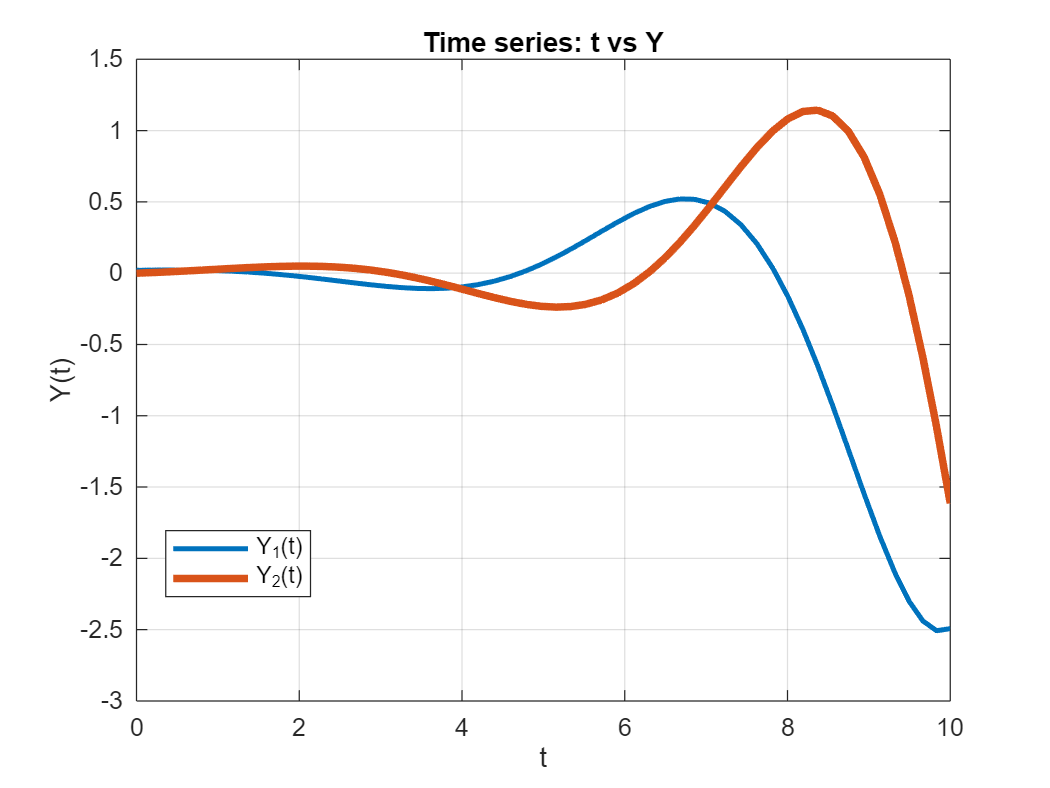

figure
plot(t, Y(:,1),'LineWidth', 2);
hold on;
plot(t, Y(:,2),'LineWidth', 2);
xlabel('t');
ylabel('Y(t)');
legend('Y_1(t)','Y_2(t)','Location','best');
title('Time series: t vs Y');
grid on;
hold off;
g=gca;
g.Children(1).LineWidth=3;

#### Stable Spiral (Spiral Sink)

Similar to the unstable spiral, it calculates a vector field, solves the differential equations, and animates the trajectory. However, in this case, the trajectory spirals inward toward the origin rather than outwards


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=-y-x\left(1-x^2 -y^2 \right)\\
\frac{\textrm{dy}}{\textrm{dt}}=x-y\left(1-x^2 -y^2 \right)
\end{array}$$


% Stable Spiral Example with Phase Plot and Animation
clear; clc; close all;

% Define the system of ODEs
f = @(t, Y) [ -Y(2) - Y(1)*(1 - Y(1)^2 - Y(2)^2);  % dx/dt
              Y(1) - Y(2)*(1 - Y(1)^2 - Y(2)^2) ];  % dy/dt


Now set up phase plot

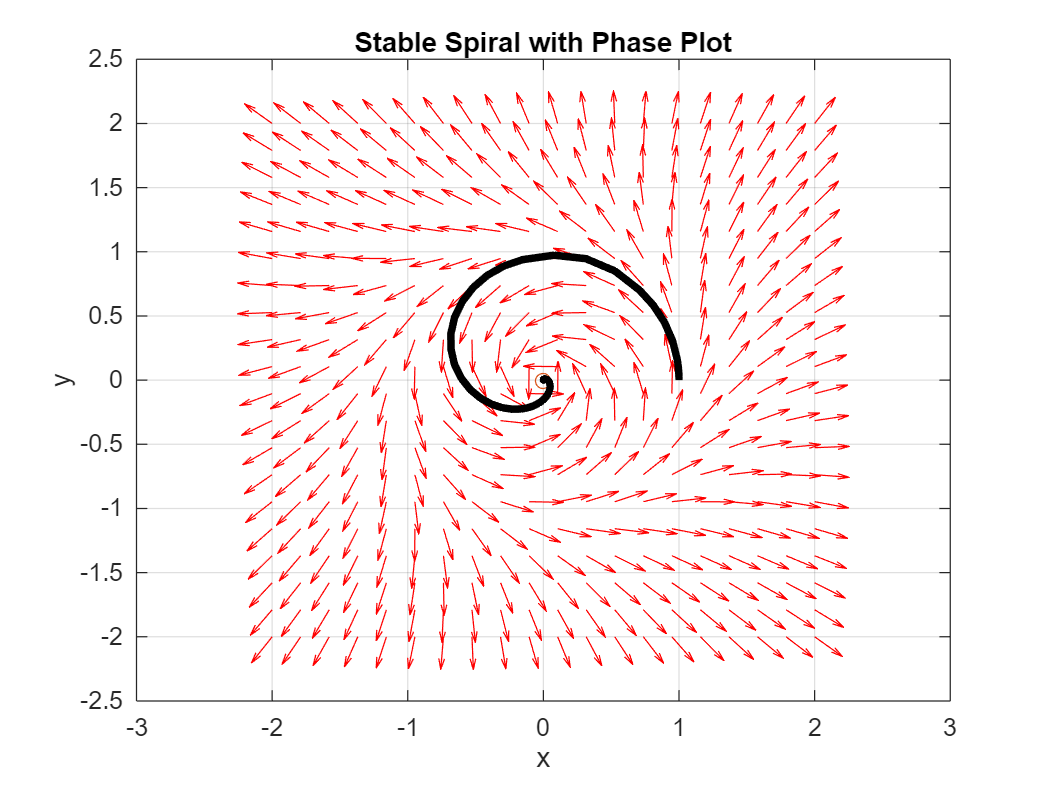


% Set up time span and initial conditions
tspan = [0 25];
s0 = [1.0, 0.0];  % Initial conditions that start near the origin

% Create a grid for the phase plot
y1 = linspace(-2, 2, 20);
y2 = linspace(-2, 2, 20);
[x, s] = meshgrid(y1, y2);
u = zeros(size(x));
v = zeros(size(s));

% Compute the vector field for phase plot
for i = 1:numel(x)
    Yprime = f(0, [x(i); s(i)]);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end

% Plot the vector field (phase plot)
figure;
mag = sqrt(u.^2+v.^2);
quiver(x, s, u./mag, v./mag, 'r'); % Vector field
hold on;

% Solve the ODE
[t, s] = ode45(f, tspan, s0);

% Animate the trajectory using comet
comet(s(:,1), s(:,2)); % Animation using comet

% Add labels and title
xlabel('x');
ylabel('y');
title('Stable Spiral with Phase Plot');
grid on;
hold off;
g=gca;
g.Children(1).LineWidth=3;
g.Children(1).Color='k';

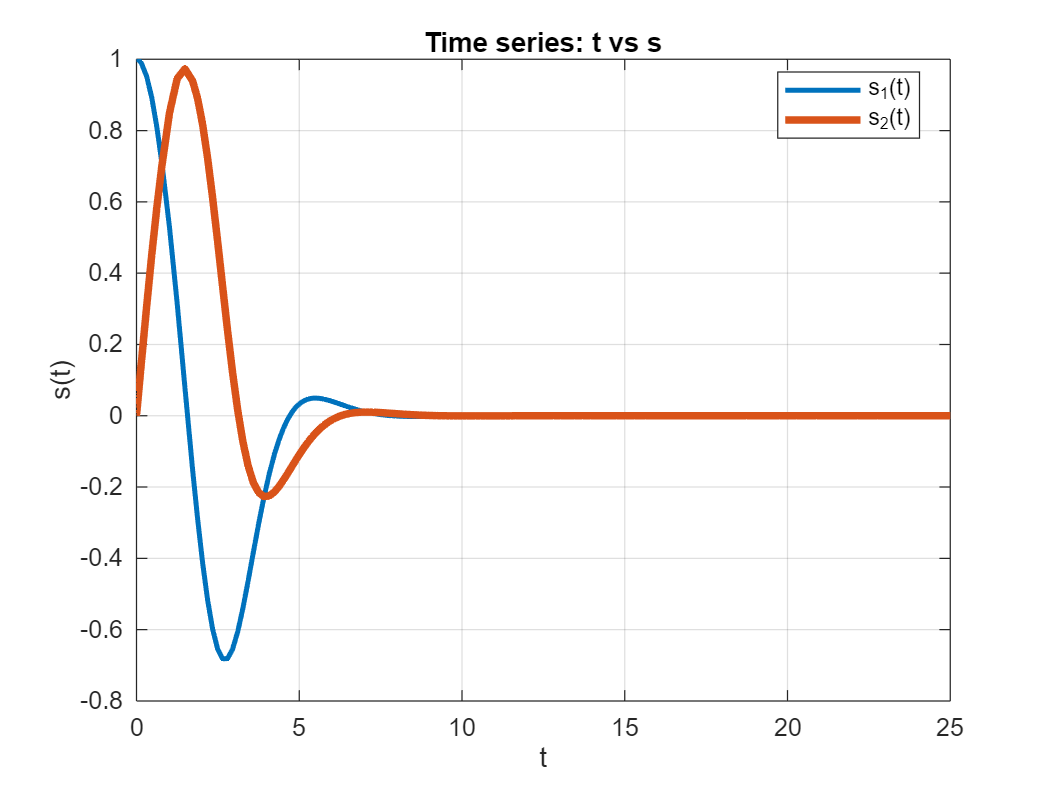

figure
plot(t, s(:,1),'LineWidth', 2);
hold on;
plot(t, s(:,2),'LineWidth', 2);
xlabel('t');
ylabel('s(t)');
legend('s_1(t)','s_2(t)','Location','best');
title('Time series: t vs s');
grid on;
hold off;
g=gca;
g.Children(1).LineWidth=3;

#### Saddle Point

Unlike stable and unstable spirals, a saddle point has directions where solutions move toward equilibrium and other directions where solutions move away from it.


$$\begin{array}{l}
\frac{\mathrm{dx}}{\mathrm{dt}}=-x\\
\frac{\mathrm{dy}}{\mathrm{dt}}=y
\end{array}$$


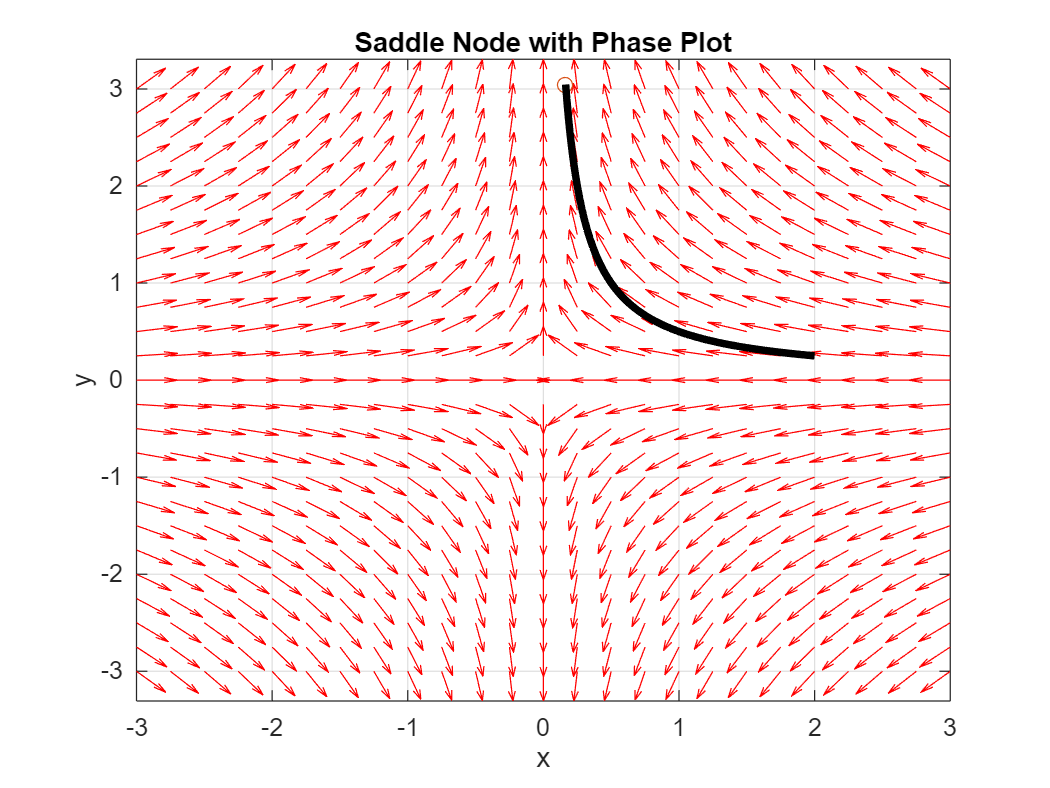

% Saddle Node Example with Phase Plot and Animation
clear; clc; close all;

% Define the system of ODEs
f = @(t, Y) [ -Y(1);  % dx/dt
              Y(2)]; % dy/dt

% Set up time span and initial conditions
tspan = [0 2.5];
s0 = [2, 0.25];  % Initial conditions near the equilibrium point

% Create a grid for the phase plot
y1 = linspace(-3, 3, 25);
y2 = linspace(-3, 3, 25);
[x, s] = meshgrid(y1, y2);
u = zeros(size(x));
v = zeros(size(s));

% Compute the vector field for phase plot
for i = 1:numel(x)
    Yprime = f(0, [x(i); s(i)]);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end

% Plot the vector field (phase plot)
figure;
mag = sqrt(u.^2+v.^2);
quiver(x, s, u./mag, v./mag, 'r'); % Vector field
hold on;

% Solve the ODE
[t, s] = ode45(f, tspan, s0);

% Animate the trajectory using comet
comet(s(:,1), s(:,2)); % Animation using comet

% Add labels and title
xlabel('x');
ylabel('y');
title('Saddle Node with Phase Plot');
grid on;
hold off;
axis tight
g=gca;
g.Children(1).LineWidth=3;
g.Children(1).Color='k';

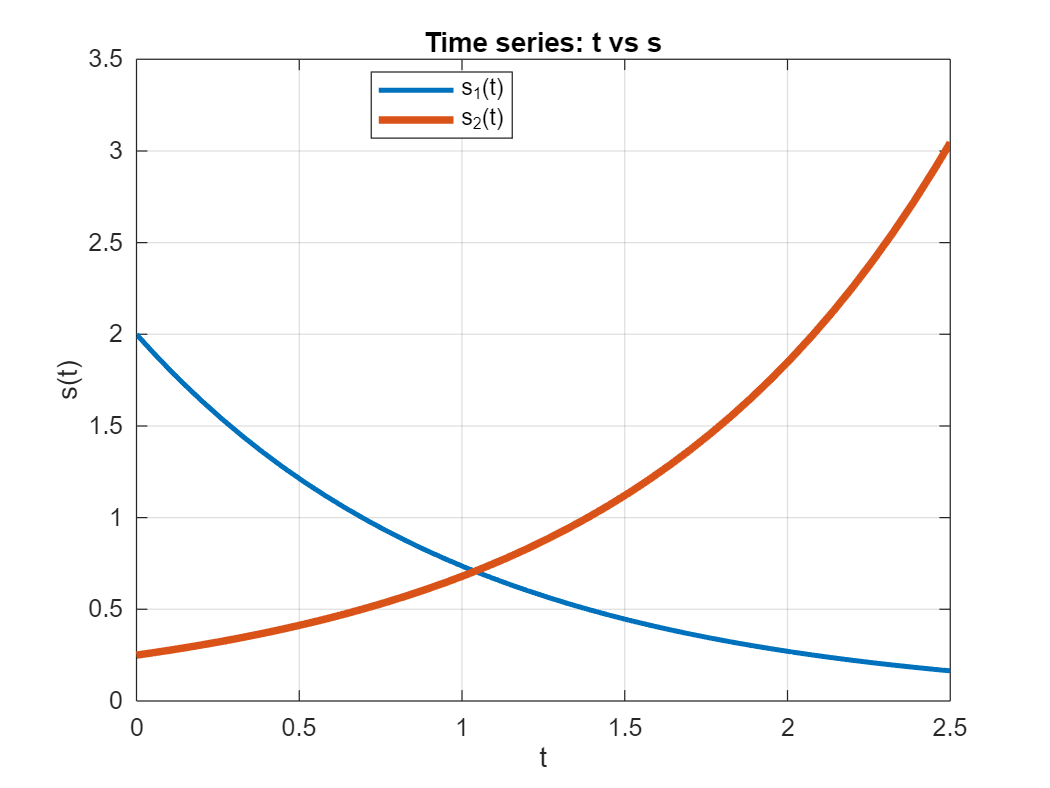

figure
plot(t, s(:,1),'LineWidth', 2);
hold on;
plot(t, s(:,2),'LineWidth', 2);
xlabel('t');
ylabel('s(t)');
legend('s_1(t)','s_2(t)','Location','best');
title('Time series: t vs s');
grid on;
hold off;
g=gca;
g.Children(1).LineWidth=3;

#### Numerical Integration of ODEs (A Review)

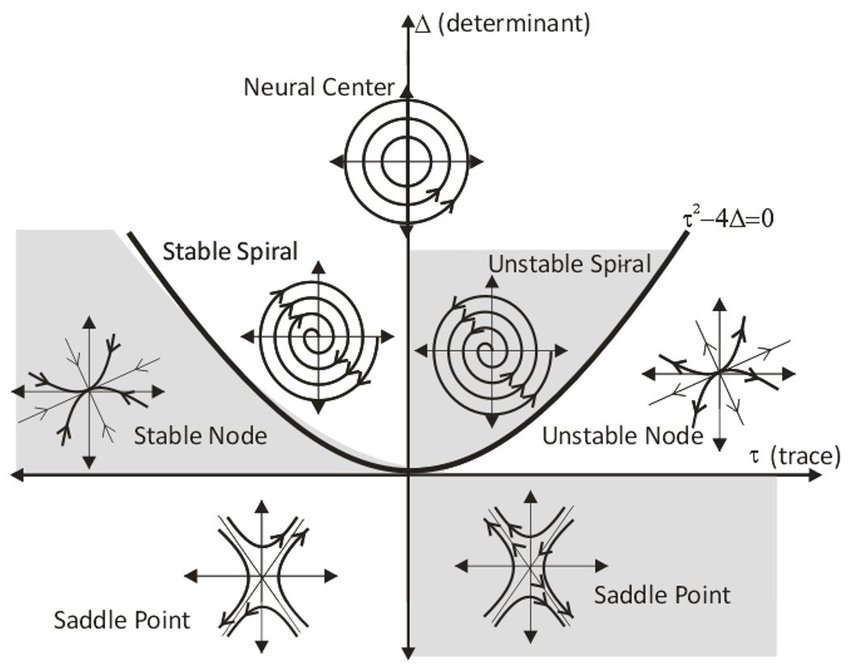

- Dynamics of physiological systems may be modeled using systems of ODEs, and their behavior can be observed through integrating (meaning, simulating) those models.

- Higher order ODEs may be transformed into systems of first order ODEs for simulation using canonical methods.

- Integration methods are based on local first-order approximations: move in the direction of the slope and re-evaluate the slope at the next time-step until reaching the final step.

- Many factors influence numerical solutions, **ALL** of which are approximations.